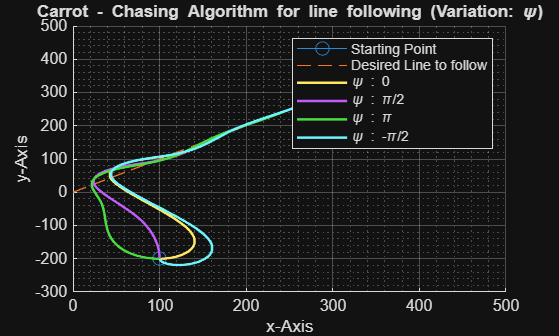

%Carrot - chasing algorithm for Straight line following
%with variations in Initial Heading Angle psi;
clear;
clc;
dt = 0.001;
w1 = [0,0];
w2 = [450,450];
delta = 15;
va = 25;
Rmin = 10;
l = sqrt((w1(1) - w2(1))^2 + (w1(2) - w2(2))^2);
theta = atan2(w2(2) - w1(2), w2(1) - w1(1));

pos = [100,-200];
figure;
hold on;
plot(pos(1), pos(2), marker = 'o', markersize = 8);
plot([w1(1), w2(1)], [w1(2), w2(2)], LineStyle='--');

k = 0.5;
target = [0,0];

for psi = [0, pi/2, pi, -pi/2]
    position = pos';
    p = pos;
    tempsi = psi;

    Ru = sqrt((w1(1) - p(1))^2 + (w1(2) - p(2))^2);
    thetau = atan2(p(2) - w1(2), p(1) - w1(1));
    beta = theta - thetau;
    R = sqrt(Ru^2 - (Ru*sin(beta))^2);
    
    while R + delta <= l
        Ru = sqrt((w1(1) - p(1))^2 + (w1(2) - p(2))^2);
        thetau = atan2(p(2) - w1(2), p(1) - w1(1));
        beta = theta - thetau;
        R = sqrt(Ru^2 - (Ru*sin(beta))^2);
        
        target(1) = w1(1) + (R + delta)*cos(theta);
        target(2) = w1(2) + (R + delta)*sin(theta);
        
        psid = atan2(target(2) - p(2), target(1) - p(1));
        u = k*(psid - tempsi)*va;
        tempsi = psid - saturate(va, Rmin, u)/(k*va);
        tempsi = tempsi + k*(psid - tempsi)*dt;
    
        p(1) = p(1) + va*cos(tempsi)*dt;
        p(2) = p(2) + va*sin(tempsi)*dt;
        position = [position p'];
    end
    
    position = position';
    plot(position(:,1), position(:,2), linewidth = 1.5);
end
grid on;
grid minor;
xlabel('x-Axis');
ylabel('y-Axis');
legend("Starting Point","Desired Line to follow","\psi : 0","\psi : \pi/2","\psi : \pi","\psi : -\pi/2");
title('Carrot - Chasing Algorithm for line following (Variation: \psi)');
hold off;


function an = saturate(va, Rmin, u)
    if abs(u) > va^2/Rmin
        if u < 0
            an = -va^2/Rmin;
        else
            an = va^2/Rmin;
        end
    else
        an = u;
    end
end